data = readtable('C:\Users\n\OneDrive - The Ohio State University\Project\Data\Fatigue_tests\Vertical_flats_fatiguelife\Fatigue_Life_Tests_iteration_1\bar4_4-4_fatiguelife_6-5kn_neg2kn_cyclesstress.xlsx')

data = 372238×9 table
      time       force     cycles     stress     Var5    Var6    Var7    Var8    Var9
    ________    _______    _______    _______    ____    ____    ____    ____    ____

    0.076986    0.21908    0.19246     14.965    NaN     NaN     NaN     NaN     NaN 
     0.14372    0.45121    0.35929      30.82    NaN     NaN     NaN     NaN     NaN 
     0.21045    0.68088    0.52612     46.508    NaN     NaN     NaN     NaN     NaN 
     0.27718    0.91914    0.69295     62.783    NaN     NaN     NaN     NaN     NaN 
     0.34391      1.157    0.85978     79.033    NaN     NaN     NaN     NaN     NaN 
     0.41064     1.3939     1.0266     95.211    NaN     NaN     NaN 

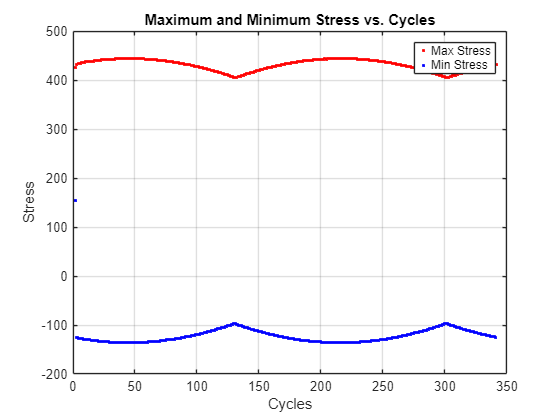

stress = data{:, 4};
cycles = data{:, 3};
% time = data{:, 'time'};
% force = data{:, 'force'};

% Compute cycles and stress
% cycles = time * 2.5;
% stress = (force * 1000) / 14.64;

% Add the new columns to the data table
% data.Cycles = cycles;
% data.Stress = stress;

[maxpk, maxloc] = findpeaks(stress);
[minpk, minloc] = findpeaks(-stress);
extremevals = [maxpk.', -minpk.'];
extremlocs = [maxloc.', minloc.'];

% Correct the minima since we inverted stress
minpk = -minpk;

% Get the corresponding cycle counts for max and min stress values
cycles_max = cycles(maxloc);
cycles_min = cycles(minloc);

% Plot the maximum and minimum stress versus cycles
figure;
plot(cycles_max, maxpk, 'r.', cycles_min, minpk, 'b.');
xlabel('Cycles');
ylabel('Stress');
legend('Max Stress', 'Min Stress');
title('Maximum and Minimum Stress vs. Cycles');
grid on;